clear all
close all
clc
format shortEng
% Shoot for 35 Bar and 35 GPM. can do two pumps


% Conversions
Bar2Pa = 100000;
Gal2MCubed = 0.0037854;
M2S = 60;
H2S = M2S*60;
LipoVoltage = 3.7;
InCubed2Gal = 0.004329;
InCubed2MCubed = 1.6387e-5;
RPM2Rads = pi/30;

% Equations:
syms TotalPower RotationalPower HeatPower
syms Torque W RPM
syms Rcoil I Vcoil
syms Vback KV RPM V
syms PumpPower Vdot deltaP
syms PumpDisplacement
eq1 = TotalPower == RotationalPower + HeatPower;
eq2 = RotationalPower == Torque*W;
eq3 = W == (2*pi/60)*RPM;
eq4 = HeatPower == Rcoil*I^2;
eq5 = RPM == Vback*KV;
eq6 = Vcoil == V - Vback;
eq7 = PumpPower == Vdot*deltaP;
eq8 = RPM == (Vdot/PumpDisplacement)*M2S;
eq9 = Torque == I/(KV*RPM2Rads);
eq10 = HeatPower == Vcoil*I;

% Calculations
Pressure = 35; %bar
PumpDisplacement = 1.2855*InCubed2MCubed; %M^3/Rev
GPM = 0.1:0.1:35; %GPM
Vdot = GPM*Gal2MCubed/M2S; %M^3/S
deltaP = Pressure*Bar2Pa;
Rcoil = [57;33;101;12;22;95;17;1.9;30;20]*(1/1000); %Ohm
KV = [120;420;100;100;120;80;80;180;245;325];
LipoCells = [12;8;12;24;14;14;24;12;10;8];
Vrated = LipoCells*LipoVoltage;

%solving the equations:
PumpPower = eval(solve(eq7,PumpPower));
MaxPumpPower = max(PumpPower)

MaxPumpPower =      7.7285e+003


RotationalPower = PumpPower;
RPM = eval(solve(eq8,RPM));
max(RPM)

ans =      6.2894e+003


Vback = eval(solve(eq5,Vback));
W = eval(solve(eq3,W));
MaxW = max(W)

MaxW =    658.6230e+000


Torque = eval(solve(eq2,Torque));
Torque(1) %torque is constant at a constant pressure rise

ans =     11.7344e+000


I = eval(solve(eq9,I));
I(:,1)

ans =    147.4584e+000
   516.1045e+000
   122.8820e+000
   122.8820e+000
   147.4584e+000
    98.3056e+000
    98.3056e+000
   221.1876e+000
   301.0609e+000
   399.3666e+000


HeatPower = eval(solve(eq4,HeatPower));
HeatPower(:,1)

ans =      1.2394e+003
     8.7900e+003
     1.5251e+003
   181.1999e+000
   478.3677e+000
   918.0794e+000
   164.2879e+000
    92.9555e+000
     2.7191e+003
     3.1899e+003


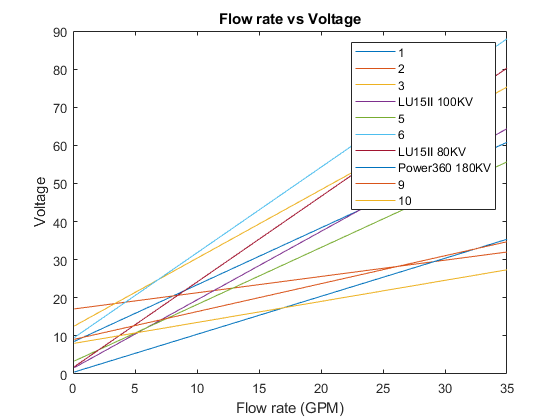

Vcoil = eval(solve(eq10,Vcoil));
V = eval(solve(eq6,V));
plot(GPM,V)
legend('1','2','3','LU15II 100KV','5','6','LU15II 80KV','Power360 180KV','9','10')
title('Flow rate vs Voltage');
xlabel('Flow rate (GPM)');
ylabel('Voltage') 

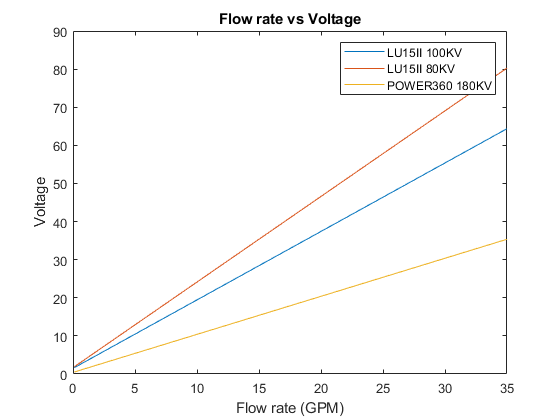

plot(GPM,V(4,:),GPM,V(7,:),GPM,V(8,:))
legend('LU15II 100KV','LU15II 80KV','POWER360 180KV')
title('Flow rate vs Voltage');
xlabel('Flow rate (GPM)');
ylabel('Voltage')

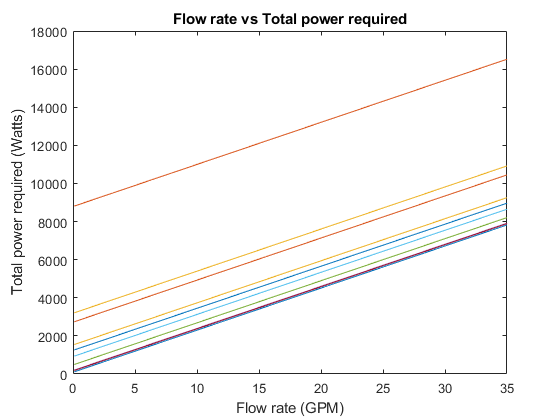

TotalPower = eval(solve(eq1,TotalPower));
plot(GPM,TotalPower)
title('Flow rate vs Total power required');
xlabel('Flow rate (GPM)');
ylabel('Total power required (Watts)')

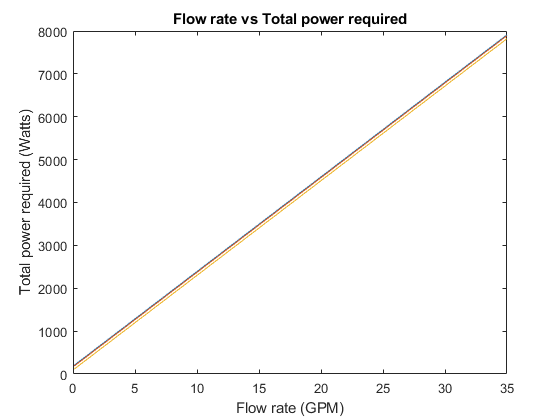

plot(GPM,TotalPower(4,:),GPM,TotalPower(7,:),GPM,TotalPower(8,:))
title('Flow rate vs Total power required');
xlabel('Flow rate (GPM)');
ylabel('Total power required (Watts)') 